close all;
clear;
Fs = 48000;
test1 = load('Normal Baseline Data 12K/Normal_0_1797_rpm.mat'); % 29.95 Hz
freqRot = 29.95; % tours/min → Hz
acc=test1.X097_DE_time;
acc=acc((48000*4)+1:(48000*5));
speedMax = 50;% Hz
speedMin = 1;% Hz
dec = 8;

% plot(acc)
% ylabel('Accélération (g)')
% title('raw signal')
% plotFFT(acc,Fs);

% Envelope Extraction avec complex mmodulation

% Envelope Extraction

acc = decimate(acc, dec, 8, 'fir');
Fs = Fs /dec;
signalEnvelope = getEnv(acc, Fs, 500);  %   extracts the envelope



% ACF old Computation

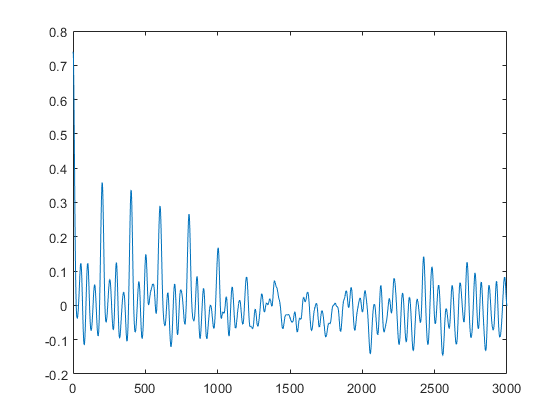

simpleACF = getAcf(signalEnvelope);  %   computes the ACF
figure;
plot(simpleACF);   

ACF new

opts = struct();
        opts.unbiased   = false;
        opts.normalize  = true;
        opts.window        = 'none' ;  % or "hann"
        opts.maxLagSec   = Inf;
  

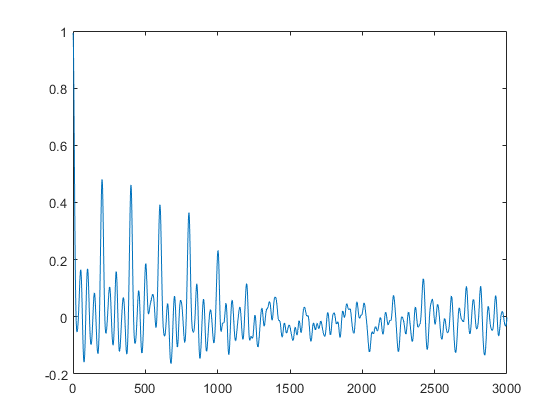

      
[lags, compare2, info]= acf_fft_band(signalEnvelope, Fs, 100, 1,opts);
figure;
plot(compare2);  

ACF Variante non biaisée (comparaison robuste entre tailles de fenêtre) :

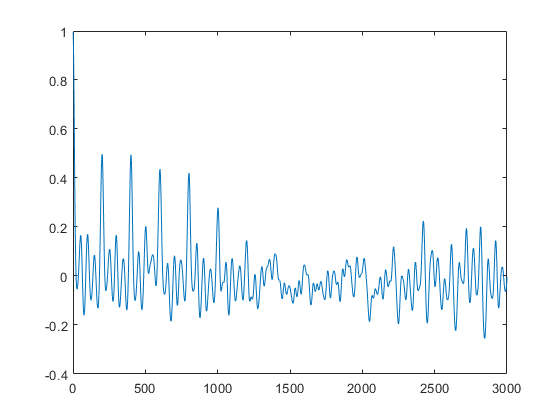

opts.unbiased = true;
[ lags, compare3 ] = acf_fft_band(signalEnvelope, Fs, 100,1, opts);
figure;
plot(compare3);  

ACF Ajouter une fenêtre de Hann sur x (si fort leakage) :

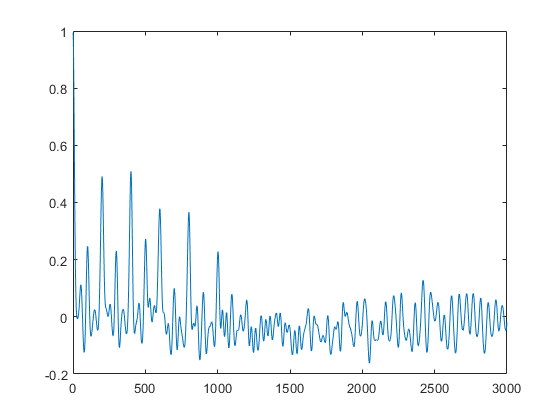

opts.window = 'hann';
[ lags, compare4 ] = acf_fft_band(signalEnvelope, Fs, 100,1, opts);
figure;
plot(compare4);    

McLeod Peak plus net

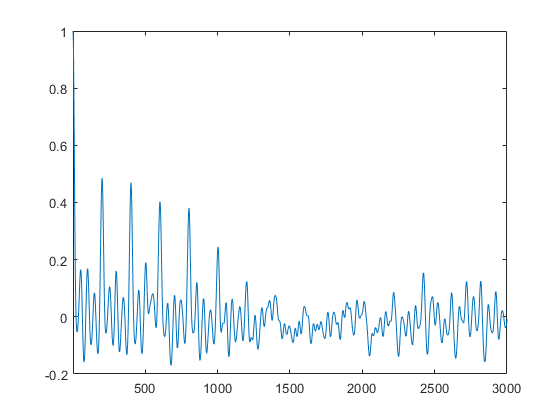

%%

[nsdf] = nsdf_mcleod_fast(signalEnvelope, Fs, 0.5, 120, 1.0);
figure;
plot(nsdf);
xlim([1 3000]);

%%


CorEntropy plus robuste

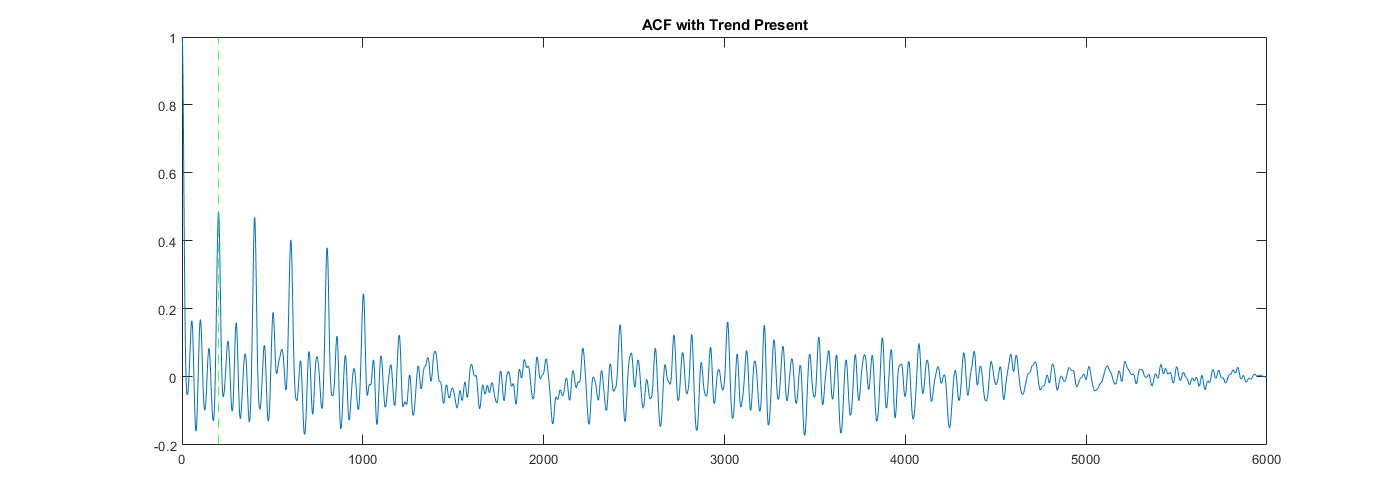

% xm = median(signalEnvelope);
% sig = 1.4826*median(abs(signalEnvelope - xm)) + eps;
% sig = max(sig, 1e-6);
% CorEntropySig = compute_correntropy_signal(signalEnvelope, numel(signalEnvelope)/2, sig);
% figure;
% plot(CorEntropySig);      
% Choisi quel style ACF
ACF = nsdf;

% Plotting ACF with Trend
figureHandle = figure;
plot(ACF);
% hold on;
% plot(simpleACF);
xline(Fs/freqRot, 'g--');  % Marking the frequency line
title('ACF with Trend Present');
set(figureHandle, 'Position', [100 100 1400 500]);  % Adjusting figure position and size

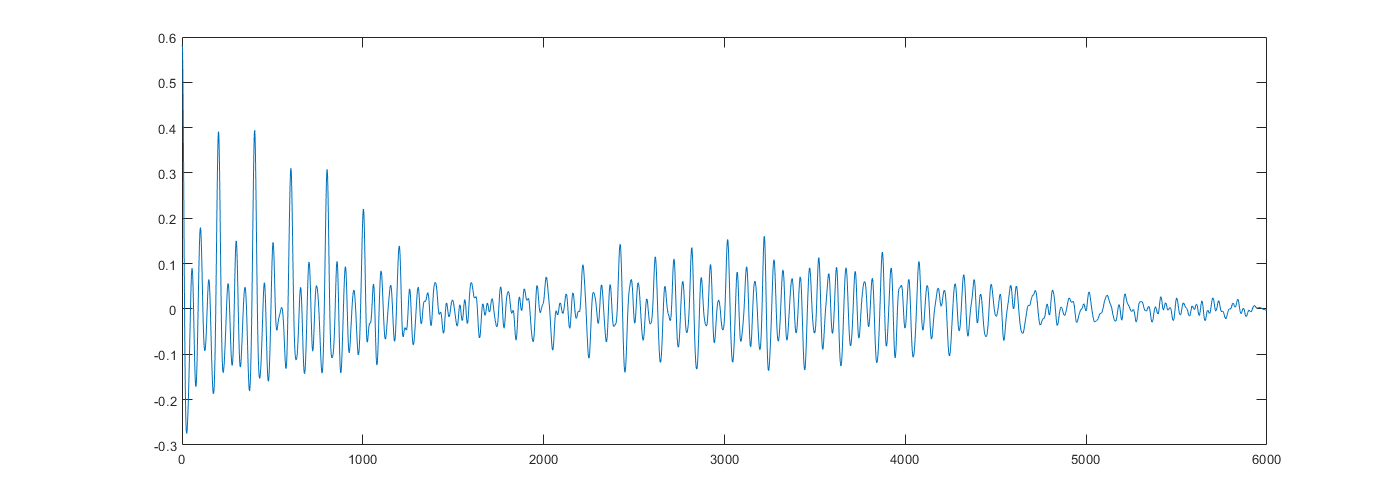



% Detrending the ACF Signal
acfDetrended = detrendHodrickPrescott(ACF);
plot(acfDetrended);

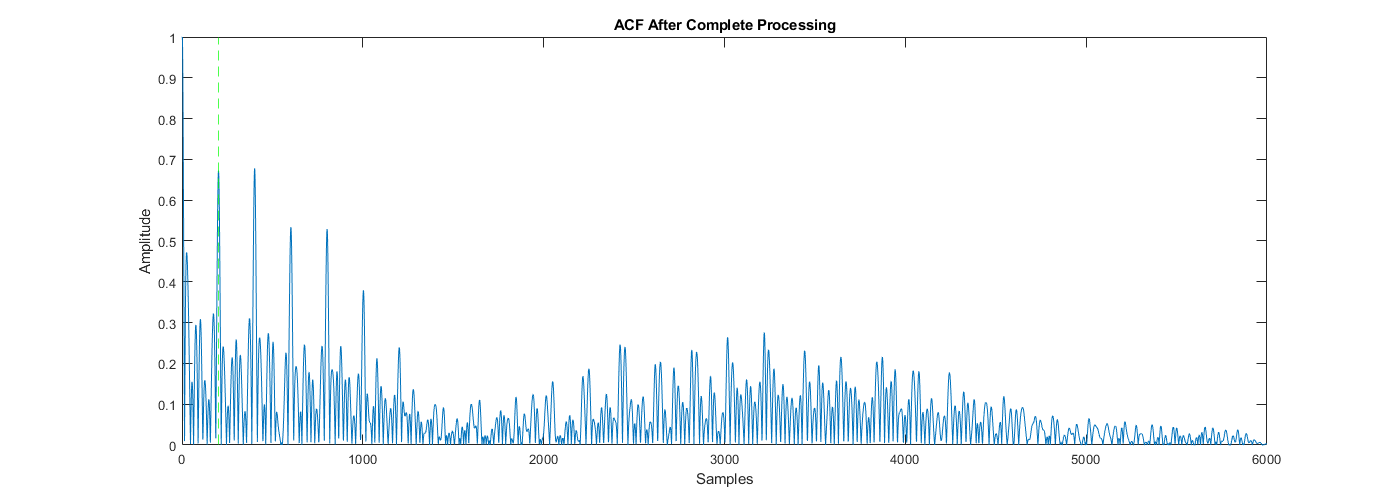






% Enhancing Peaks and Reducing Noise in Detrended ACF
% -----------------------------------------------------

acfHuber = huber(acfDetrended);

% Normalization of ACF Between 0 and 1
% This normalization step makes the data more uniform and easier to analyze.
acfHuber = normalize_0_1(acfHuber);

% Plotting the Processed ACF
figureHandle = figure;
plot(acfHuber);
xline(Fs/freqRot, 'g--');  % Marking the frequency line
xlabel('Samples');
ylabel('Amplitude');
title('ACF After Complete Processing');
set(figureHandle, 'Position', [100 100 1400 500]);

parametres





acf_n = acfHuber(:);
MaxLagSec =   1.0; % analyser l'ACF jusqu'à 1 s
TopPeaks =   6; % # pics max pour la médiane des intervalles
Prominence = 0.05;  % proéminence min (fraction du max hors lag 0)
SmoothMs =   2.0;   % lissage avant détection de pics (ms)
PsdFmax  =   300;    
fmin        = 0.5;     % bande de recherche (Hz)
fmax        = 120;     % bande de recherche (Hz)
Kharm       = 6;       % # d'harmoniques pour le peigne odd/even
lambdaEven  = 0.8;     % pénalisation de l'énergie paire
gammaHalf   = 1.0;    % si R(T/2) > gamma*R(T) ET even>odd => demi-tour probable
Threshold   = 0.15;    % seuil YIN (0.1–0.2 typique)
WeightMode  = '1/k';   % 'equal' ou '1/k'
Eps         = 1e-3;    % epsilon dans log( eps + R+ )
HPS_K      = 4;        % # harmoniques HPS
HPS_dfHz   = 0.1;      % pas Hz pour HPS


Nlag   = numel(acf_n);
% ---------- bornes en lag ----------
tauMinSamp = max(2, floor(Fs / fmax)); % >= 2 pour parabolique on ne cherche pas de période plus courte que 1/fmax, et jamais en dessous de 2 échantillons.
tauMaxSamp = min(Nlag-2, ceil(Fs / fmin));% on ne cherche pas de période plus grande que 1/fmin, ni au-delà de ce que l’ACF permet.
maxLagSamp = min(Nlag-1, round(MaxLagSec*Fs));% borne maximale imposée par un paramètre utilisateur (MaxLagSec).
tauMaxSamp = min(tauMaxSamp, maxLagSamp);% la borne maximale effective est la plus restrictive des deux.

if tauMinSamp+2 >= tauMaxSamp
    error('Plage de lag invalide: ajuster fmin/fmax/MaxLagSec.');
end

lags = (0:Nlag-1).';% [0 ,1 ,2 ... ,5999]
tau  = lags / Fs;% [0 ,0.0002 ,0.0003,... ,0.999] 



Détection des pics le Max (le plus simple)

AcfIn = acfHuber(:);
AcfIn(1:ceil(Fs/120)) = 0;
[pkVal, pkLoc] = max(AcfIn);
[T_hat,Lref] =interp_parabolic_acf(AcfIn, pkLoc, Fs, numel(AcfIn));
tauMaxSamp = numel(AcfIn);
Kharm = 6;

[L0, S] = pickL_from_acf_harmonics(AcfIn, Lref, Kharm, tauMaxSamp, true);
candf_nsdf_pk = Fs/L0;


Estimation de période par médiane des différences successives

% ---------- Détection de pics ACF Mediane ----------
% wSamp représente la taille de la fenêtre de lissage (en nombre d’échantillons) appliquée sur l’ACF.
% wSamp = max(1, round(SmoothMs * 1e-3 * Fs)); % P.SmoothMs * 1e-3 * Fs : convertit la durée de lissage en nombre d=échantillons.
% acf_s = normalize_0_1(movavg(acf_n, wSamp));
acf_s = acf_n;

% seuil de proéminence (relatif au max hors lag 0)
base = max(acf_s(2:min(end,maxLagSamp+1)));
prom = Prominence * max(base, eps);
% impose une distance min entre pics pour éviter les doublons (≈ T/3 à fmax)
minPkDist = max(2, round(0.33 * Fs / fmax));

% À partir de l’ACF (lags >= 0) :
[pkVal, pkLoc] = findpeaks(AcfIn, 'MinPeakProminence', prom, 'MinPeakDistance', minPkDist);   % pkLoc = lags, pkVal = amplitudes

[L_best, score, keptIdx, keptVal, H, diag] = pick_f0_by_self_harmonics( ...
    pkLoc, pkVal, 8, 'RelTol', 0.06, 'nTopCand', 30, 'MinHarmHit', 2);


[T_hat,L_ref] =interp_parabolic_acf(acf_s, L_best, Fs, tauMaxSamp);
fr_best1 = Fs / L_ref;  

huberK = 0.8 %≈0.4–0.8

huberK = 0.8000

[L_refined, Lh, wh] = refine_L_from_harmonics(AcfIn, keptIdx, keptVal, H, huberK);
candf_nsdf_pk_mediane = Fs / L_refined;

fprintf('Fréquence       f ≈ %.3f Hz\n', candf_nsdf_pk_mediane);

Fréquence       f ≈ 29.865 Hz


Estimateur YIN/CMNDF

% 1B (ACF + YIN/CMNDF),
[L, idxRange, dprime] = yin_pick_L_from_acf_cmndf(AcfIn, Fs, tauMinSamp, tauMaxSamp, Threshold, true, 0.10);
% On choisit le pic le plus proche de T_samp et on récupère sa position entière L.
[T_hat,Lref] =interp_parabolic_acf(dprime, L, Fs, tauMaxSamp);


opts = struct();
opts.dprime_s = dprime;
opts.UseYIN = true;
[candf_yin, T_hat, DEC] = anti_half_acf_unified(AcfIn, Fs, T_hat, tauMaxSamp, Kharm, lambdaEven, gammaHalf, opts);

[L0, S] = pickL_from_acf_harmonics(AcfIn, Lref, Kharm, tauMaxSamp, true);
candf_yin = Fs/L0;
fprintf('Fréquence       f ≈ %.3f Hz\n', candf_yin);

Fréquence       f ≈ 29.851 Hz


Estimateur par peigne Log

% 2) Parametres peigne-produit (log)

opts = struct();
opts.Kharm = Kharm;
opts.WeightMode = WeightMode; 
opts.Eps = Eps; 
opts.gridStepSamp = 2; 
opts.needAtLeastHarm = 2; 
[Lbest, Sbest] = scorePeigneGridRefine(acf_s, tauMinSamp, tauMaxSamp, opts);
[T_hat,~] =interp_parabolic_acf(acf_s, Lbest, Fs, tauMaxSamp);
opts.UseYIN = false;
[candf_comb, T_hat, DEC] = anti_half_acf_unified(acf_s, Fs, T_hat, tauMaxSamp, Kharm, lambdaEven, gammaHalf, opts);
fprintf('Fréquence       f ≈ %.3f Hz\n', candf_comb);

Fréquence       f ≈ 29.925 Hz


Estimateur HPS

[candf_hps, L0] = cand_hps_from_psd(AcfIn, Fs, fmin, fmax, HPS_dfHz, HPS_K);
opts.UseYIN = false;
[candf_hps, T_hat, DEC] = anti_half_acf_unified(AcfIn, Fs, L0/Fs, tauMaxSamp, Kharm, lambdaEven, gammaHalf, opts);
fprintf('Fréquence       f ≈ %.3f Hz\n', candf_hps);

Fréquence       f ≈ 29.975 Hz


% Decide

fcands = [candf_yin, candf_nsdf_pk, candf_comb, candf_hps,candf_nsdf_pk_mediane];
fcands = fcands(isfinite(fcands) & fcands>0);% -------------------- (2) Fusion robuste (consensus) --------------------
% médiane sur log-f : robuste aux outliers multiplicatifs / erreurs d’octave
lf = log(fcands);
f_cons = exp(median(lf));
% cohérence des méthodes (plus c’est petit, mieux elles s’accordent)
disp_log = mad(lf,1);             % MAD sur log-f (échelle robuste)
q_cons   = max(0, 1 - disp_log/0.25);   % heuristique ~1 si accord ±25%

% -------------------- (3) Anti-demi-tour multi-votes --------------------
Tcand = 1/f_cons;

% Fusion 3 votes : peigne ACF (odd/even), peigne spectral (odd/even), ratio R(T) vs R(T/2)
SpecBW_Hz  = 1.0;                 % demi-largeur bande (Hz) pour énergie PSD
K = Kharm;
wk = weights_K(K, WeightMode);
tauMax = numel(acf_s)-1;  interpR = @(q) safe_interp((0:tauMax).', acf_s, q);

% (1) Peigne ACF
[sComb_T, ~, ~] = comb_score(acf_s, Tcand*Fs, K, wk, lambdaEven, true);
[sComb_H, ~, ~] = comb_score(acf_s, (Tcand*Fs)/2, K, wk, lambdaEven, true);

% (2) Peigne spectral
[Fspec, Pxx] = psd_from_acf(acf_s, Fs);
BW = max(SpecBW_Hz, Fspec(2)-Fspec(1)); 
Spec = @(f0) band_energy(Fspec, Pxx, f0, BW);
f0 = 1/Tcand; fH = 2/Tcand;
sSpec_T = odd_even_spec(Spec, f0, K, wk, lambdaEven);
sSpec_H = odd_even_spec(Spec, fH, K, wk, lambdaEven);

% (3) Ratio ACF
RT = interpR(Tcand*Fs); RH = interpR((Tcand*Fs)/2);
sRatio_T = (RT - gammaHalf*RH);
sRatio_H = (RH - gammaHalf*RT);
nr = max(abs([sRatio_T sRatio_H])) + eps; sRatio_T = sRatio_T/nr; sRatio_H = sRatio_H/nr;


% poids vote
wComb      = 0.45; 
wSpec = 0.40; 
wRratio = 0.15; 
% Score global & décision
S_T = wComb*sComb_T + wSpec*sSpec_T + wRratio*sRatio_T;
S_H = wComb*sComb_H + wSpec*sSpec_H + wRratio*sRatio_H;
if S_H > S_T
    f_corr = fH;   % utiliser T/2 -> double fréquence
else
    f_corr = f0;   % garder T
end
fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', f_corr, 60*f_corr);

f_hat  = 29.873 Hz   (rpm ≈ 1792.4)


plot

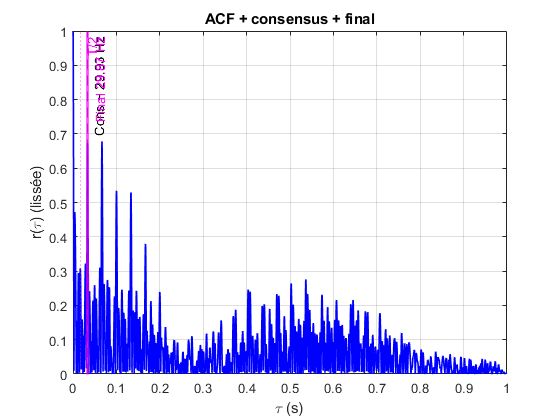


 % 1) ACF + positions T, T/2
    figure('Name','ACF (one frame)','Color','w');
    plot(tau, acf_s, 'b-','LineWidth',1.2); grid on; hold on;
    xline(1/candf_comb, 'k--', sprintf('Cons ~ %.2f Hz', candf_comb));
    xline(1/f_corr,'m-', sprintf('Final %.2f Hz', f_corr), 'LineWidth',2);
    xline(0.5/f_corr,'m:', 'T/2');
    xlabel('\tau (s)');
    ylabel('r(\tau) (lissée)');
    title('ACF + consensus + final');

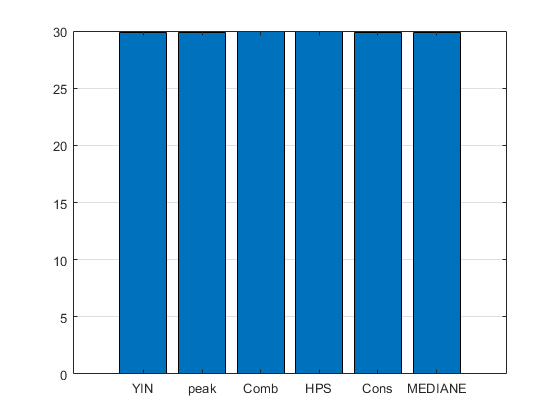


    % 2) Barres candidats & quality
    figure('Name','Candidats & Qualité','Color','w');
    vals = [candf_yin, candf_nsdf_pk, candf_comb, candf_hps, f_cons,candf_nsdf_pk_mediane];
    names= {'YIN','peak','Comb','HPS','Cons','MEDIANE'};
    bar(vals); grid on; set(gca,'XTick',1:numel(vals),'XTickLabel',names);

      %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% % Profil “MCU” (opérations simples, K=3 harmoniques, peu de divisions)
% P = struct();
% P.fmin = 0.5; P.fmax = 120;    % bande recherche
% P.maxLagSec = 1.0;             % borne ACF analysée
% P.minProm   = 0.05;            % proéminence min (relatif au max hors lag0)
% P.smoothN   = 3;               % lissage ACF (moy. mobile) — 1,2,3 échantillons
% P.minPkDist = [];              % distance min entre pics (auto si vide)
% P.Kharm     = 3;               % # harmoniques pour le peigne odd/even
% P.gammaHalf = 1.15;            % seuil R(T/2) > gamma*R(T)
% P.lambdaEven= 0.85;            % pénalisation énergie paire
% P.roundMult = true;            % (MCU) évaluer k*T au plus proche échantillon (pas d’interp)
% P.parabolic = true;            % petite interp. parabolique locale (désactivable sur MCU)
% P.Plot      = true;            % tracés de validation PC
% 
% [fr_hat, OUT] = reco_mcu_acf(acfHuber(:), Fs, P);
% 
% fprintf('\n--- Reco MCU (ACF-only) ---\n');
% fprintf('f_hat  = %.3f Hz   (rpm ≈ %.1f)\n', fr_hat, 60*fr_hat);
% fprintf('T_hat  = %.6f s   periodicity=%.3f   q=%.2f\n', OUT.T_hat, OUT.periodicity, OUT.q);




interéssant pour Kalman example de trois fenêtre glissante

% %% --- Paramètres fenêtre glissante ---
% WinSec  = 0.60;            % longueur fenêtre (s)
% HopSec  = 0.20;            % pas temps entre fenêtres (s)
% MaxLagS = min(0.80*WinSec, 1.0);   % ACF analysée jusqu'à 80% fenêtre, cap 1 s
% fmin    = 0.5;             % Hz
% fmax    = 120;             % Hz
% 
% % NSDF / McLeod + anti-demi-tour (par fenêtre)
% P = struct();
% P.MaxLagSec   = MaxLagS;
% P.fmin        = fmin;
% P.fmax        = fmax;
% P.MinNSDF     = 0.55;      % crête NSDF min (0.4–0.8)
% P.SmoothMs    = 1.0;       % lissage NSDF (ms)
% P.PeakGuard   = 0.1;       % recherche fine ±10% de la crête
% P.Kharm       = 4;         % peigne odd/even (k=1..K)
% P.lambdaEven  = 0.8;       % pénalisation des pairs
% P.gammaHalf   = 1.12;      % seuil demi-tour
% P.ACFMode     = 'normalized'; % on normalise R(0)=1 par fenêtre
% P.Nproxy      = [];        % (inutile ici)
% P.Plot        = false;
% 
% % Kalman (état [f; fdot], discret, modèle vitesse constante)
% KAL = struct();
% KAL.dt     = HopSec;      % pas entre mesures
% KAL.f0     = 20;          % init f (Hz)
% KAL.fdot0  = 0;           % init dérivée (Hz/s)
% KAL.sigma_fdot = 2.0;     % écart-type accélération (Hz/s)
% KAL.sigma_meas = 0.8;     % écart-type mesure (Hz)
% KAL.adapt_from_nsdf = true;% ajuste R selon la qualité NSDF
% %% --- Tracking ---
% [tt, f_meas, f_kal, diagFrames] = track_fr_nsdf_from_acf(acc, Fs, WinSec, HopSec, P, KAL);

function [lags, acf, info] = acf_fft_band(x, Fs, fmin, fmax, opts)
% ACF_FFT_BAND  Autocorrelation (FFT-based, linear) limited to [fmin..fmax]
% 
% [lags, acf, info] = acf_fft_band(x, Fs, fmin, fmax, opts)
% 
% Inputs:
%   x     : signal (vector)
%   Fs    : sampling rate [Hz]
%   fmin  : lowest fundamental of interest [Hz]   (sets tauMaxSamp)
%   fmax  : highest fundamental of interest [Hz]  (sets tauMinSamp)
%   opts  : struct with optional fields:
%           .unbiased  (logical, default=false)  % divide each lag by (L-k)
%           .normalize (logical, default=true)   % acf(0)=1
%           .window    ('none'|'hann', default='none') % window on x
%           .maxLagSec (scalar, optional)        % extra upper cap in seconds
%
% Outputs:
%   lags  : vector of lags [samples], starting at tauMinSamp..tauMaxSamp
%   acf   : ACF(tau) aligned with lags
%   info  : struct with fields:
%           .tauMinSamp, .tauMaxSamp, .L, .nfft
%
% Notes:
% - Removes DC (mean) before FFT.
% - Uses zero-padding >= 2L-1 for LINEAR ACF (not circular).
% - Use unbiased=true if you want comparability across window sizes.

%     arguments
%         x (:,1) double
%         Fs (1,1) double {mustBePositive}
%         fmin (1,1) double {mustBePositive}
%         fmax (1,1) double {mustBePositive}
%         opts.unbiased  logical = false
%         opts.normalize logical = true
%         opts.window    char    = 'none'   % or "hann"
%         opts.maxLagSec double  = Inf
%     end

    % --- pre
    x = x(:);
    L = numel(x);
    if fmax >= Fs/2
        warning('fmax >= Fs/2; setting fmax = 0.45*Fs'); 
        fmax = 0.45*Fs;
    end
    if fmin <= 0
        error('fmin must be > 0');
    end
    if fmax >= fmin
        warning('fmax >= fmin; swapping to enforce fmax < fmin.');
        tmp = fmax; fmax = fmin; fmin = tmp;
    end

    % --- tau bounds from band
    tauMinSamp = max(1, floor(Fs / fmax));             % smallest lag we trust
    tauMaxBand = floor(Fs / fmin);                      % largest lag from fmin
    tauMaxUser = min(L-1, floor(opts.maxLagSec * Fs));  % user/size cap
    tauMaxSamp = min([tauMaxBand, tauMaxUser, L-1]);

    if tauMinSamp > tauMaxSamp
        % Degenerate band -> fall back to [1 .. min(ceil(L/2), L-1)]
        tauMinSamp = 1;
        tauMaxSamp = min(ceil(L/2), L-1);
%         warning('Band limits collapsed; using fallback tau range [%d..%d].', ...
%                  tauMinSamp, tauMaxSamp);
    end

    % --- optional window on x (avoid strong edge effects if needed)
    switch lower(opts.window)
        case 'hann'
            w = hann(L);
            xw = (x - mean(x)) .* w;
        otherwise
            xw = x - mean(x);   % remove DC is crucial
    end

    % --- FFT-based linear ACF
    nfft = 2^nextpow2(2*L - 1);
    X = fft(xw, nfft);
    S = X .* conj(X);
    r = ifft(S, 'symmetric');   % linear ACF thanks to zero-padding
    r = r(1:L);                 % lags >= 0

    % --- biased / unbiased
    if opts.unbiased
        k = (0:L-1).';
        denom = max(L - k, 1);
        r = r ./ denom;
    end

    % --- normalization (so acf(0)=1)
    if opts.normalize
        r0 = max(r(1), eps);
        r = r / r0;
    end

    % --- crop to banded lags [tauMinSamp .. tauMaxSamp]
    lags = (tauMinSamp:tauMaxSamp).';
    acf  = r(lags + 1);   % +1 because r(1) is lag 0

    % --- info
    info = struct('tauMinSamp',tauMinSamp, 'tauMaxSamp',tauMaxSamp, ...
                  'L',L, 'nfft',nfft, 'fmin',fmin, 'fmax',fmax);
end



function acf = getAcf(SigEnv)
    % Compute the Autocorrelation Function (ACF) of the Signal Envelope

    % Perform the Fourier Transform of the Signal Envelope
    fftSignal = fft(SigEnv);

    % Compute the Power Spectrum
    % This is the modulus squared of the FFT, which gives the power at each frequency
    powerSpectrum = abs(fftSignal) .^ 2;

    % Compute the Inverse Fourier Transform of the Power Spectrum
    % This yields the autocorrelation function of the signal
    acfFull = ifft(powerSpectrum);

    % Extract the first half of the ACF
    % The ACF is symmetric, so the first half contains all the unique information
    acf = acfFull(1:round(numel(acfFull)/2));
end

function xEnv = getEnv(signal, Fs, cutOff)
    % Extract the Envelope of a Signal Using Complex Demodulation
    % Parameters:
    %   signal: The input signal from which to extract the envelope.
    %   Fs: Sampling frequency of the signal.
    %   cutOff: Cut-off frequency for the low-pass filter.

    % Define the filter order
    FilterOrder = 50;

    % Create a time vector corresponding to the signal
    t = (0:length(signal) - 1)' / Fs;

    % Perform complex demodulation
    % This shifts the signal frequency content around the cut-off frequency to baseband
    x0 = signal .* exp(-1i * 2 * pi * cutOff * t);

    % Design a low-pass FIR filter
    % The effective cut-off frequency is halved as the signal is shifted to baseband
    b = fir1(FilterOrder,  cutOff/2 / Fs/2);

    % Apply the low-pass filter
    % The filter is applied to extract the low-frequency components (envelope)
    xEnv = conv2(x0, b(:), 'same') * 2;

    % Compute the magnitude of the complex signal
    % This step extracts the envelope of the original signal
    xEnv = abs(xEnv);

    % Remove the DC component from the envelope
    % This centers the envelope around zero, removing any constant ofFset
    xEnv = xEnv - mean(xEnv);
end


function normalizedData = normalize_0_1(data)
    % Find the minimum and maximum values of the input data
    dataMin = min(data);
    dataMax = max(data);

    % Check if dataMax and dataMin are the same (to avoid division by zero)
    if dataMax == dataMin
        % If all data points are equal, return a zero array of the same size
        normalizedData = zeros(size(data));
    else
        % Normalize the data to the range [0, 1]
        normalizedData = (data - dataMin) / (dataMax - dataMin);
    end
end



function acfDetrended = detrendHodrickPrescott(acf)
% Hodrick-Prescott Filter for Detrending ACF
% -------------------------------------------

% Initialize the autocorrelation function
Y = acf(:);

% Smoothing Parameter
% Note: The smoothing value should be in accordance with the sampling rate.
smoothing = 1e+6;

% Number of Observations
numObs = numel(acf);

% Constructing the Hodrick-Prescott Filter Coefficients
% Normally this would be a sparse matrix for efficiency, but here we use a full matrix.
e = repmat([smoothing, -4 * smoothing, (1 + 6 * smoothing), -4 * smoothing, smoothing], numObs, 1);
A = spdiags(e, -2:2, numObs, numObs);
% Adjusting the first and last rows of matrix A for boundary conditions
A(1,1) = 1 + smoothing;
A(1,2) = -2 * smoothing;
A(2,1) = -2 * smoothing;
A(2,2) = 1 + 5 * smoothing;
A(numObs-1, numObs-1) = 1 + 5 * smoothing;
A(numObs-1, numObs) = -2 * smoothing;
A(numObs, numObs-1) = -2 * smoothing;
A(numObs, numObs) = 1 + smoothing;

% LU Decomposition for Solving the Filter
% L for lower triangular matrix and U for upper triangular matrix
[L, U, P] = lu(A);

% Solving the System Using LU Decomposition
y = L \ (P * Y);  % Solving Ly = Pb using forward substitution
trend = U \ y;    % Solving Ux = y using backward substitution

% Detrending the ACF Signal
acfDetrended = Y - trend;  % Subtracting the trend component
end

function acfHuber = huber(acf)
% Median and Mean Absolute Deviation (MAD) Calculation
mu = median(acf);  % Median of the detrended ACF
s = mean(abs(acf - mu));  % Mean absolute deviation around the median

% Applying the Huber Function
% The Huber function is a robust method of scaling data. 
x = (acf' - mu) / s;
result = sign(x) .* min(abs(x), s);  % Applying Huber function to scale the data

% Applying the Huber Function Results to the ACF
acfHuber = acf' .* result;
end

% --------- sous-fonctions locales ---------
function y = movavg(x,w)
% moyenne mobile (filtfilt si possible, sinon conv), colonne en sortie
x = double(x(:));
k = ones(w,1)/w;
try
    y = filtfilt(k,1,x);
catch
    y = conv(x,k,'same');
end
y = cast(y, 'like', x);
end



function [pks, locs] = findpeaks_safe(x, varargin)
% utilise findpeaks si dispo (Signal Toolbox), sinon fallback
try
    [pks, locs] = findpeaks(x, varargin{:});
catch
    p = inputParser;
    p.addParameter('MinPeakProminence', 0);
    p.addParameter('MinPeakDistance', 1);
    p.parse(varargin{:});
    prom = p.Results.MinPeakProminence;
    mind = p.Results.MinPeakDistance;
    locs = [];
    for i=2:numel(x)-1
        if x(i)>x(i-1) && x(i)>x(i+1) && x(i)>prom
            if isempty(locs) || (i - locs(end)) >= mind
                locs(end+1)=i; %#ok<AGROW>
            end
        end
    end
    pks = x(locs);
end
end

function v = safe_interp(x, y, q)
% interpolation linéaire sûre aux indices fractionnaires (en échantillons)
% x : 0..Nlag-1, y : même taille, q : scalaire (ou vecteur) en "samples"
q = q(:);
v = nan(size(q));
Nlag = numel(x);
for i=1:numel(q)
    if q(i) < 1 || q(i) > Nlag-2
        v(i) = NaN; %#ok<*AGROW>
    else
        i0 = floor(q(i));
        a  = q(i) - i0;
        v(i) = (1-a)*y(i0+1) + a*y(i0+2);
    end
end
if isscalar(v), v=v(1); end
end



% ===== PSD à partir de l'ACF (Wiener–Khinchin) =====
function [F, Pxx] = psd_from_acf(acf_n, Fs)
% ACF symétrisée : r[-k] = r[k]
acf_sym = [flipud(acf_n(2:end)); acf_n(:)];
% fenêtre Hann (évite les fuites dues au troncage)
Nlag = numel(acf_sym);
n = (0:Nlag-1).';
w = 0.5 - 0.5*cos(2*pi*n/(Nlag-1)); % fenetre de Hann
R = acf_sym .* w; % appliques cette fenêtre à l’ACF avant de faire la FFT :
% PSD = FFT(R) réelle (procès réel)
S = fft(R);
Pxx = real(S(1:floor(Nlag/2)+1));
F   = (0:floor(Nlag/2)).' * (Fs/Nlag);
end


function [T_hat, Lref] = interp_parabolic_acf(acf_s, L, Fs, tauMaxSamp)
% INTERP_PARABOLIC_ACF
% Raffine la position d'un pic ACF par interpolation parabolique (3 points).
% - Fallback sûr si proche des bords ou si la courbure n'est pas concave.
%
% In:
%   acf_s       : ACF (déjà lissée de préférence), vecteur colonne/ligne
%   L           : indice entier du pic (1-based, tel que acf_s(L) est le pic)
%   Fs          : fréquence d'échantillonnage (Hz)
%   tauMaxSamp  : borne max utile en lag (en échantillons)
%
% Out:
%   T_hat       : période raffinée (secondes)  = Lref / Fs
%   Lref        : position raffinée du pic (échantillons, fractionnaire)

acf_s = acf_s(:);                 % assure colonne
Nlag     = numel(acf_s);
tauMaxSamp = min(tauMaxSamp, Nlag-1);

% --- Cas bords : pas assez de points (il faut L-1, L, L+1)
if ~(L >= 2 && L <= tauMaxSamp-1)
    Lref  = double(L);            % fallback : pas d'interp
    T_hat = Lref / Fs;
    return;
end

% --- Parabole 3 points
y1 = double(acf_s(L-1));
y2 = double(acf_s(L));
y3 = double(acf_s(L+1));

% Conditions de validité :
% 1) y2 au moins aussi grand que ses voisins (pic local)
% 2) courbure concave : (y1 - 2*y2 + y3) < 0
if (y2 < y1) && (y2 < y3)
    % clair creux -> pas d'interp
    Lref  = double(L);
    T_hat = Lref / Fs;
    return;
end
den = (y1 - 2*y2 + y3);
if ~(den < 0)
    % pas un maximum concave exploitable -> fallback
    Lref  = double(L);
    T_hat = Lref / Fs;
    return;
end

% Décalage sous-échantillon (théorie parabole)
delta = 0.5 * (y1 - y3) / den;

% Clamp pour éviter sauts aberrants quand les 3 points sont plats/bruités
delta = max(min(delta, 0.5), -0.5);

% Position raffinée
Lref  = double(L) + delta;
% Sécurité bornes (en cas d'arrondi limite)
Lref  = max(1, min(Lref, double(tauMaxSamp)));

% Période (s)
T_hat = Lref / Fs;
end



function [L, idxRange, dprime] = yin_pick_L_from_acf_cmndf(r_ns, Fs, tauMinSamp, tauMaxSamp, thresh, useAdaptive, winProp)
% YIN_PICK_L_FROM_ACF_CMNDF
%  Sélection du lag fondamental via YIN/CMNDF depuis une ACF déjà
%  normalisée & lissée (r_ns). Ne fait PAS de parabole ici.
%
% In:
%   r_ns        : ACF normalisée ET lissée (colonne/ligne), r_ns(1)=1
%   Fs          : Hz (utilisé seulement pour cohérence d'unités; ici pas critique)
%   tauMinSamp  : lag mini (samples)   ~ floor(Fs/fmax), forcé >= 2
%   tauMaxSamp  : lag maxi (samples)   ~ ceil(Fs/fmin)
%   thresh      : seuil YIN (p.ex. 0.10–0.20)
%   useAdaptive : true/false → abaisse le seuil si pas de crossing
%   winProp     : largeur de fenêtre locale autour du crossing (ex: 0.10)
%
% Out:
%   L        : lag entier choisi (samples)
%   idxRange : [i1 i2] fenêtre locale utilisée pour le min (utile pour ta parabole)
%   dprime   : CMNDF (utile pour debug/plots en aval)
%
% Hypothèses:
%  - r_ns est déjà pré-traitée (centrage/normalisation, lissage) ailleurs.
%  - L’interpolation parabolique sera appliquée ailleurs à partir de L.

% --- garde-fous sur la bande ---
r_ns = r_ns(:);
Nlag = numel(r_ns);
tauMinSamp = max(2, floor(tauMinSamp));
tauMaxSamp = min(max(tauMinSamp+2, floor(tauMaxSamp)), Nlag-1);

% --- CMNDF: d(τ)=2*(1-r(τ)), d'(τ)=d(τ)*τ / cumsum(d) ---
tauIdx = (1:tauMaxSamp).';
d      = 2.0 * (1 - r_ns(tauIdx+1));
cum    = cumsum(d);
dprime = d .* (tauIdx ./ max(cum, eps));

% --- masque bande (ignore < tauMinSamp) ---
dprime(1:tauMinSamp-1) = +Inf;

% --- seuil absolu + option adaptative ---
idx = find(dprime < thresh, 1, 'first');
if isempty(idx) && useAdaptive
    % seuil adaptatif simple vers le minimum observé dans la bande
    dband = dprime;
    dband(~isfinite(dband)) = +Inf;
    mval  = min(dband);
    th2   = max(0.05, min(0.95, 0.5*(thresh + mval)));
    idx   = find(dprime < th2, 1, 'first');
end

% --- sélection du minimum local autour du premier crossing (ou min global) ---
if ~isempty(idx)
    firstIdx = idx;                                   % déjà en indices absolus car dprime est tronqué seulement en <tauMin
    win      = max(3, round(winProp * firstIdx));     % ex: 10% de τ
    i1       = max(tauMinSamp, firstIdx - win);
    i2       = min(tauMaxSamp, firstIdx + win);
    [~,rel]  = min(dprime(i1:i2));
    L        = i1 + rel - 1;
    idxRange = [i1 i2];
else
    % pas de crossing → minimum global dans la bande
    [~,L] = min(dprime);
    if L<tauMinSamp || L>tauMaxSamp
        [~,L] = min(dprime(tauMinSamp:tauMaxSamp));
        L = L + tauMinSamp - 1;
    end
    idxRange = [max(tauMinSamp, L-3), min(tauMaxSamp, L+3)]; % petite fenêtre par défaut
end
end



function out = tern(c,a,b), if c, out=a; else, out=b; end, end

function dp = interp_dprime(dprime, q)
Nlag = numel(dprime);
if q<1, q=1; end, if q>Nlag-1, q=Nlag-1; end
i0 = floor(q); a = q - i0;
dp = (1-a)*dprime(i0) + a*dprime(i0+1);
end

function [fr_hat, T_hat, DEC] = anti_half_acf_unified(r_in, Fs, T_hat_in, tauMaxSamp, K, lambdaEven, gammaHalf, opts)
% ANTI_HALF_ACF_UNIFIED
%  Décide entre T, T/2 (et optionnellement 2T) en combinant :
%   - ratio ACF : R(T/2) vs R(T)
%   - peigne odd/even ACF
%   - (option) critère YIN : d'(T/2) << d'(T)
%
% In:
%   r_in        : ACF (lags >=0). Peut être brute; on normalise R(0)=1.
%   Fs          : Hz
%   T_hat_in    : période candidate (secondes)
%   tauMaxSamp  : max lag utile (échantillons)
%   K           : nb harmoniques pour peigne odd/even (2..6)
%   lambdaEven  : pondération "even" (0.8..1.0)
%   gammaHalf   : seuil ratio R(T/2) > gamma * R(T) (1.05..1.2)
%   opts (struct, facultatif):
%       .UseYIN      (default true)  % utilise dprime_s si fourni
%       .dprime_s    ([])            % CMNDF lissée si dispo
%       .Lref        ([])            % lag frac. correspondant à T_hat_in (échantillons)
%       .Consider2T  (default true)  % essaie aussi 2T
%       .ClampBand   ([fmin fmax])   % clamp final en Hz (ex: [0.5 120])
%
% Out:
%   fr_hat  : fréquence corrigée (Hz)
%   T_hat   : période corrigée (s)
%   DEC     : diagnostics (struct)

if nargin<8, opts = struct(); end
if ~isfield(opts,'UseYIN'),     opts.UseYIN = true; end
if ~isfield(opts,'dprime_s'),   opts.dprime_s = []; end
if ~isfield(opts,'Lref'),       opts.Lref = []; end
if ~isfield(opts,'Consider2T'), opts.Consider2T = true; end
if ~isfield(opts,'ClampBand'),  opts.ClampBand = []; end

% --- normalisation sûre ---
r = r_in(:);
r = r / max(r(1), eps);
lags = (0:numel(r)-1).';

interpR = @(q) safe_interp(lags, r, q);   % linéaire
T   = max(1/Fs, T_hat_in);
Ts  = T * Fs;                              % en échantillons
tauMaxSamp = min(tauMaxSamp, numel(r)-1);

% --- fonctions utilitaires ---
function S = comb_odd_even(Tsamp)
    Sodd=0; Seven=0;
    for kk=1:K
        q = kk*Tsamp;
        if q<=tauMaxSamp
            val = interpR(q); val = max(val,0);
            if mod(kk,2)==1, Sodd=Sodd+val; else, Seven=Seven+val; end
        end
    end
    S = (Sodd - lambdaEven*Seven) / max(Sodd + lambdaEven*Seven, eps);
end

% --- scores pour T, T/2, (2T option) ---
RT  = interpR(Ts);
RT2 = interpR(Ts/2);
S_T  = comb_odd_even(Ts);
S_H  = comb_odd_even(Ts/2);

scoreT  = (RT  - gammaHalf*max(RT2,0)) + 0.20*S_T;
scoreH  = (RT2 - gammaHalf*max(RT ,0)) + 0.20*S_H;

% Critère YIN optionnel
yinBoost_T = 0; yinBoost_H = 0;
if opts.UseYIN && ~isempty(opts.dprime_s)
    % si Lref inconnu, approx via T*Fs
    Lref = tern(~isempty(opts.Lref), opts.Lref, Ts);
    dT  = interp_dprime(opts.dprime_s, Lref);
    dH  = interp_dprime(opts.dprime_s, Lref/2);
    if isfinite(dT) && isfinite(dH)
        if dH < 0.85 * dT, yinBoost_H = 0.15; end  % bonus si vallée T/2 nettement meilleure
    end
end
scoreT = scoreT + yinBoost_T;
scoreH = scoreH + yinBoost_H;

% Option 2T
score2 = -Inf; T2 = 2*T; S_2 = NaN; R2 = NaN;
if opts.Consider2T
    R2 = interpR(2*Ts);
    S_2 = comb_odd_even(2*Ts);
    score2 = (R2 - gammaHalf*max(RT,0)) + 0.20*S_2;
end

% Décision
[~,ix] = max([scoreT, scoreH, score2]);
if ix==2
    T_hat = T/2;
elseif ix==3
    T_hat = T*2;
else
    T_hat = T;
end

% Clamp bande fréquence (facultatif)
fr_hat = 1 / max(T_hat, eps);
if ~isempty(opts.ClampBand) && numel(opts.ClampBand)==2
    fr_hat = min(max(fr_hat, opts.ClampBand(1)), opts.ClampBand(2));
    T_hat  = 1 / fr_hat;
end

% Diagnostics
combContrast = comb_odd_even(T_hat*Fs);
DEC = struct('RT',RT,'RT2',RT2,'R2',R2, ...
             'S_T',S_T,'S_H',S_H,'S_2',S_2, ...
             'scoreT',scoreT,'scoreH',scoreH,'score2',score2, ...
             'combContrast',combContrast);
end

function [Lbest, Sbest] = scorePeigneGridRefine(acf_s, tauMinSamp, tauMaxSamp, opts)
% SCOREPEIGNEGRIDREFINE
%  Peigne log sur ACF lissée/normalisée (positif), échantillonné sur une grille grossière,
%  puis raffinement local à pas 1 et interpolation parabolique du score.
%
% In:
%   acf_s        : ACF (déjà lissée de préférence), colonne/ligne
%   tauMinSamp   : lag min (samples)
%   tauMaxSamp   : lag max (samples)
%   opts struct  :
%       .Kharm        (default 6)
%       .WeightMode   (default '1/k')   % or 'equal'
%       .Eps          (default 1e-3)
%       .gridStepSamp (default 2)       % grille grossière (>=1)
%       .needAtLeastHarm (default 2)    % nb mini d'harmoniques
%
% Out:
%   Lbest  : lag entier (échantillons) après raffinement local
%   Sbest  : score peigne au meilleur L (sans parabolique)

if nargin<4, opts = struct(); end
if ~isfield(opts,'Kharm'),        opts.Kharm = 6; end
if ~isfield(opts,'WeightMode'),   opts.WeightMode = '1/k'; end
if ~isfield(opts,'Eps'),          opts.Eps = 1e-3; end
if ~isfield(opts,'gridStepSamp'), opts.gridStepSamp = 2; end
if ~isfield(opts,'needAtLeastHarm'), opts.needAtLeastHarm = 2; end

acf_s = acf_s(:);
Nlag  = numel(acf_s);
tauMaxSamp = min(tauMaxSamp, Nlag-1);

% ---- Poids ----
K  = opts.Kharm;
if strcmpi(opts.WeightMode,'equal')
    wk = ones(1,K);
else
    wk = 1./(1:K);
end
wk = wk / sum(wk);

% ---- Préparation ----
rpos   = max(acf_s, 0);
logeps = @(x) log(opts.Eps + x);

% ---- Grille grossière ----
gridStep = max(1, round(opts.gridStepSamp));
tauGrid  = (tauMinSamp:gridStep:tauMaxSamp).';
Sg = numel(tauGrid);
ScoreG = -inf(Sg,1);

for s=1:Sg
    Lg   = tauGrid(s);
    kmax = min(K, floor(tauMaxSamp / Lg));
    if kmax < opts.needAtLeastHarm, continue; end
    used = 1:kmax;
    wloc = wk(used); wloc = wloc / sum(wloc);
    idx  = used.*Lg + 1;        % +1 : r(1) = lag0
    vals = rpos(idx);
    ScoreG(s) = dot(wloc(:), logeps(vals(:)));
end

% Si rien d'exploitable sur la grille → fallback pic ACF
[Sm, imax] = max(ScoreG);
if ~isfinite(Sm)
    [~, Lbest] = max(acf_s(tauMinSamp:tauMaxSamp));
    Lbest = Lbest + tauMinSamp - 1;
    Lref  = double(Lbest);
    Sbest = -inf;
    return;
end
Lcand = tauGrid(imax);

% ---- Raffinement local à pas 1 (±gridStep) ----
L1 = max(tauMinSamp, Lcand - gridStep);
L2 = min(tauMaxSamp, Lcand + gridStep);
Lvec = (L1:L2);
ScoreFine = -inf(numel(Lvec),1);
for ii=1:numel(Lvec)
    L = Lvec(ii);
    kmax = min(K, floor(tauMaxSamp / L));
    if kmax < opts.needAtLeastHarm, continue; end
    used = 1:kmax;
    wloc = wk(used); wloc = wloc / sum(wloc);
    idx  = used.*L + 1;
    vals = rpos(idx);
    ScoreFine(ii) = dot(wloc(:), logeps(vals(:)));
end

[Sm2, iFine] = max(ScoreFine);
Lbest = Lvec(iFine);
Sbest = Sm2;
end

function V = compute_correntropy_signal(x, tauMax, sigma)
% V(τ) = mean( exp( - (x[n]-x[n-τ])^2 / (2σ^2) ) )
x = double(x(:));
N = numel(x);
V = zeros(tauMax+1,1);
V(1) = 1;  % à τ=0, la correntropy vaut 1 (kernel à distance nulle)
for t = 1:tauMax
    M = N - t;
    if M<=0, break; end
    d = x(1+t:N) - x(1:N-t);
    V(1+t) = mean( exp( - (d.^2) / (2*sigma^2) ) );
end
end

function nsdf = nsdf_mcleod_fast(x, Fs, fmin, fmax, MaxLagSec)
% NSDF_MCLEOD_FAST  —  NSDF (McLeod) rapide via ACF par FFT (linéaire).
% 
% [nsdf, tau, OUT] = nsdf_mcleod_fast(x, Fs, fmin, fmax, 'Name',Value,...)
%
% In:
%   x     : signal (colonne/ligne)
%   Fs    : Hz
%   fmin  : Hz (borne basse)   -> tauMax = ceil(Fs/fmin)
%   fmax  : Hz (borne haute)   -> tauMin = max(2,floor(Fs/fmax))
%   MaxLagSec  (default 1.0)  : borne dure en secondes
%
% Out:
%   nsdf : vecteur NSDF(τ), τ=0..tauMax (nsdf(1)=0 par convention ici)

%
% Complexité: O(N log N) (ACF via FFT) + O(tauMax) (dénominateur).


% ---- prep ----
x = double(x(:));

x = x - mean(x);

N = numel(x);

% ---- ACF linéaire via FFT (Wiener–Khinchin + zero-pad >= 2N-1) ----
nfft = 2^nextpow2(2*N-1);
X = fft(x, nfft);
S = X .* conj(X);
rfull = ifft(S, 'symmetric');        % taille nfft, corrélation circulaire zero-paddée
R = rfull(1:N);                      % r(τ), τ=0..N-1 (ACF linéaire pour τ>=0)

% ---- bornes lag utiles ----
tauMax_from_fmin = ceil(Fs / max(fmin, eps));
tauMax_hard      = min(N-1, round(MaxLagSec * Fs));
tauMax = min(tauMax_hard, tauMax_from_fmin);

% ---- cumuls d'énergie pour dénominateur ----
x2 = x.^2;
E  = cumsum(x2);          % E(k) = sum_{n=1..k} x[n]^2
E0 = E(end);

% ---- NSDF = 2*R(τ) / (E0 + E(N-τ))  pour τ=1..tauMax, nsdf(0)=1 ----
nsdf = zeros(tauMax+1,1);
nsdf(1) = 1;  % τ=0
for T = 1:tauMax
    denom = E0 + E(N-T);               % somme d'énergies “alignées”
    nsdf(1+T) = (2*R(1+T)) / max(denom, eps);
end

end

function [nsdfW, Vcorr, nsdfStd] = nsdf_mcleod_correntropy_mix(x, Fs, fmin, fmax, sigma, alpha)
% alpha in [0..1] : mix additif final  S = alpha*NSDF_std + (1-alpha)*Vcorr

x = double(x(:));
N = numel(x);
tauMax = min(N-2, ceil(Fs/max(fmin,eps)));
tauMin = max(2, floor(Fs/max(fmax,eps)));

% NSDF standard (pour mix)
x2 = x.^2; E = cumsum(x2); E0 = E(end);
nsdfStd = zeros(tauMax+1,1); nsdfStd(1)=1;

% Correntropy simple
Vcorr = zeros(tauMax+1,1); Vcorr(1)=1;

% NSDF pondérée par correntropy
nsdfW = zeros(tauMax+1,1); nsdfW(1)=1;

for T = tauMin:tauMax
    M = N - T;
    if M<=0, break; end
    x1 = x(1+T:N);
    x0 = x(1:N-T);
    d  = x1 - x0;

    % ----- correntropy -----
    w = exp( - (d.^2) / (2*sigma^2) );     % poids gaussiens
    Vcorr(1+T) = mean(w);

    % ----- NSDF standard -----
    R = sum(x1 .* x0);
    denomStd = E0 + E(N-T);
    nsdfStd(1+T) = (2*R) / max(denomStd, eps);

    % ----- NSDF pondérée (kernel-weighted) -----
    Rw = sum(w .* (x1 .* x0));
    denomW = sum(w .* (x1.^2 + x0.^2));
    nsdfW(1+T) = (2*Rw) / max(denomW, eps);
end

% Option : fusion additive (si tu veux un seul score robuste)
if nargin >= 6 && ~isempty(alpha)
    nsdfW = alpha*nsdfStd + (1-alpha)*Vcorr;  % score hybride
end
end

function [fhat , L0]= cand_hps_from_psd(r, Fs, fmin, fmax, dfHz, K)
% PSD via Wiener–Khinchin (ACF -> FFT), puis Harmonic Sum sur une grille f0.
[F,Pxx] = psd_from_acf(r, Fs);
fgrid = (fmin:dfHz:fmax).';
Spec = @(f) interp1(F, Pxx, f, 'linear', 0);
S = zeros(size(fgrid));
for i=1:numel(fgrid)
    f0 = fgrid(i); s=0; cnt=0;
    for k=1:K
        fk = k*f0; if fk > F(end), break; end
        s = s + Spec(fk); cnt = cnt + 1;
    end
    if cnt>=2, S(i)=s; else, S(i)=-Inf; end
end
[~,ix] = max(S);
% raffinement parabolique
if ix>1 && ix<numel(S)
    y1=S(ix-1); y2=S(ix); y3=S(ix+1);
    delta = 0.5*(y1-y3)/max(y1-2*y2+y3, eps); delta = max(min(delta,0.5),-0.5);
else
    delta = 0;
end
fhat = fgrid(ix) + delta*dfHz;
L0 = (Fs/fhat);
end

function w = weights_K(K, mode)
switch lower(string(mode))
    case "equal", w = ones(1,K);
    otherwise,    w = 1./(1:K);
end
w = w / sum(w);
end
function [scoreComb, Sodd, Seven] = comb_score(r, T_samp, K, wk, lambdaEven, useLog)
tauMax = numel(r)-1; interpR = @(q) safe_interp((0:tauMax).', r, q);
Sodd=0; Seven=0;
for k=1:K
    q = k*T_samp; if q>tauMax, break; end
    val = interpR(q); val = max(val,0);
    if useLog, val = log(1e-3 + val); end
    if mod(k,2)==1, Sodd = Sodd + wk(k)*val; else, Seven = Seven + wk(k)*val; end
end
scoreComb = (Sodd - lambdaEven*Seven) / max(abs(Sodd)+lambdaEven*abs(Seven), eps);
end

function s = odd_even_spec(Spec, f0, K, wk, lambdaEven)
Sodd=0; Seven=0;
for k=1:K
    fk = k*f0;
    if mod(k,2)==1, Sodd = Sodd + wk(k)*Spec(fk);
    else            Seven= Seven+ wk(k)*Spec(fk);
    end
end
s = (Sodd - lambdaEven*Seven) / max(Sodd + lambdaEven*Seven, eps);
end

function E = band_energy(F, Pxx, f0, bw)
if f0<=0 || f0>F(end), E=0; return; end
m = (F >= (f0-bw)) & (F <= (f0+bw));
if ~any(m), E=0; return; end
E = trapz(F(m), Pxx(m));
end

function [L0, S] = pickL_from_acf_harmonics(AcfIn, Lref, Kharm, tauMaxSamp, useInterp)
% PICKL_FROM_ACF_HARMONICS
%  Compare la somme des harmoniques de l'ACF aux multiples de Lref:
%  Lref, Lref/2, 2*Lref, puis choisit celui qui maximise la somme.
%
% In:
%   AcfIn        : ACF (lags >= 0), vecteur ligne/colonne
%   Lref         : lag de référence (en échantillons, flottant possible)
%   Kharm        : nombre d'harmoniques à sommer (ex: 6)
%   tauMaxSamp   : lag max exploitable (<= numel(AcfIn)-1)
%   useInterp    : true -> interp linéaire (plus précis), false -> round index
%
% Out:
%   L0 : lag choisi (Lref, Lref/2 ou 2*Lref)
%   S  : struct avec les sommes pour debug (S.base, S.half, S.double)

    if nargin < 5, useInterp = true; end

    AcfIn = AcfIn(:);                     % colonne
    nLag  = numel(AcfIn) - 1;             % lags valides: [0 .. nLag]
    tauMaxSamp = min(max(1, floor(tauMaxSamp)), nLag);

    H   = (1:Kharm);                      % harmoniques 1..K
    Ls  = [Lref, Lref/2, 2*Lref];         % candidats
    Sarr = zeros(1,3);

    if useInterp
        % --- Interpolation linéaire sur ACF ---
        x = (0:nLag).';                   % grille des lags
        for j = 1:3
            q = H .* Ls(j);               % positions harmoniques (flottantes)
            m = (q <= tauMaxSamp);        % masque bornes
            if any(m)
                % extrapolation=0 pour ignorer hors-borne
                v = interp1(x, AcfIn, q(m), 'linear', 0);
                % clamp négatifs légers si besoin (optionnel) :
                % v = max(v, 0);
                Sarr(j) = sum(v);
            end
        end
    else
        % --- Version indices entiers (plus rapide, moins précise) ---
        for j = 1:3
            idx = round(H .* Ls(j));
            m = (idx >= 1) & (idx <= tauMaxSamp);
            if any(m)
                Sarr(j) = sum(AcfIn(idx(m)));
            end
        end
    end

    % Décision
    [~, k] = max(Sarr);
    L0 = Ls(k);

    % Debug / diagnostics
    S = struct('base', Sarr(1), 'half', Sarr(2), 'double', Sarr(3));
end

function [L_best, score_best, keptIdx_best, keptVal_best, H_best, diag] = ...
    pick_f0_by_self_harmonics(peakIdx, peakVal, K, varargin)
% PICK_F0_BY_SELF_HARMONICS
%  Estime le lag fondamental L_best (en échantillons) en testant chaque pic
%  comme candidat fondamental Li = peakIdx(i), et en ne gardant que ses K
%  harmoniques (h=1..K) présents parmi les pics détectés, avec tolérance.
%  Pour chaque h, on garde au plus un pic (le plus fort), on somme (pondération
%  optionnelle), et on retient le Li qui maximise le score.
%
% In:
%  peakIdx : [N×1] lags (échantillons) des pics (ex: de l'ACF)
%  peakVal : [N×1] amplitudes/poids des pics
%  K       : nombre d’harmoniques considérées (h=1..K)
%
% Options (name/value):
%  'RelTol'     (0.06)   : tolérance relative ±RelTol*Li (si AbsTol vide)
%  'AbsTol'     ([])     : tolérance absolue (échantillons) (prioritaire)
%  'Weights'    ([])     : pondération w(h) (def: 1./sqrt(h))
%                          - handle @(h)->vector, ou vecteur 1..K
%  'nTopCand'   (30)     : nb de pics candidats (les plus forts)
%  'MinHarmHit' (2)      : nb min d’harmoniques trouvées pour accepter Li
%
% Out:
%  L_best       : lag fondamental estimé (échantillons)
%  score_best   : score du meilleur candidat
%  keptIdx_best : lags des pics retenus pour L_best (un max par h)
%  keptVal_best : amplitudes correspondantes
%  H_best       : numéros d’harmoniques associés à keptIdx_best
%  diag         : diagnostics (scores par candidat, mapping, etc.)
%
% Notes:
%  - Complexité ~ O(nTopCand * N). Très rapide pour N ~ 100–300.
%  - Si tu veux un poids uniforme, passe 'Weights', @(h) ones(size(h)).

% ---------- parsing options ----------
p = inputParser;
addParameter(p,'RelTol',0.06);
addParameter(p,'AbsTol',[]);
addParameter(p,'Weights',[]);
addParameter(p,'nTopCand',30);
addParameter(p,'MinHarmHit',2);
parse(p,varargin{:});
RelTol     = p.Results.RelTol;
AbsTol     = p.Results.AbsTol;
Weights    = p.Results.Weights;
nTopCand   = p.Results.nTopCand;
MinHarmHit = p.Results.MinHarmHit;

% ---------- préparation ----------
peakIdx = peakIdx(:);
peakVal = peakVal(:);
N = numel(peakIdx);
assert(N==numel(peakVal),'peakIdx/peakVal size mismatch');
assert(K>=1 && floor(K)==K,'K doit être un entier >=1');

% candidats = les nTopCand pics les plus forts
[~, ordByVal] = sort(peakVal, 'descend');
candOrd = ordByVal(1:min(nTopCand, N));
Li_list = double(peakIdx(candOrd));   % candidats fondamental Li

% pondération w(h)
h1K = (1:K).';
if isempty(Weights)
    w = 1 ./ sqrt(h1K);    % défaut doux
elseif isa(Weights,'function_handle')
    w = Weights(h1K);
else
    w = Weights(:);
    if numel(w) < K, error('Weights length < K'); end
    w = w(1:K);
end

% ---------- boucle candidats ----------
scores_all   = -inf(numel(Li_list),1);
hits_all     = zeros(numel(Li_list),1);
keptMapsCell = cell(numel(Li_list),1);

L_best       = NaN;
score_best   = -Inf;
keptIdx_best = [];
keptVal_best = [];
H_best       = [];

for ic = 1:numel(Li_list)
    Li = Li_list(ic);

    % tolérance
    if isempty(AbsTol)
        tol = RelTol * max(Li, eps);
    else
        tol = AbsTol;
    end

    % attribution harmonique h ≈ round(idx/Li)
    ratio = double(peakIdx) ./ Li;
    hCand = round(ratio);
    delta = abs(double(peakIdx) - hCand * Li);

    % garder seulement h dans [1..K] et delta <= tol
    valid = (hCand >= 1) & (hCand <= K) & (delta <= tol);
    if ~any(valid), continue; end

    vIdx = peakIdx(valid);
    vVal = peakVal(valid);
    vH   = hCand(valid);
    % (optionnel : vDel = delta(valid);)

    % un pic max par harmonique
    [uniqH, ~, grp] = unique(vH, 'stable');
    bestLag = zeros(numel(uniqH),1);
    bestVal = zeros(numel(uniqH),1);
    for u = 1:numel(uniqH)
        sel  = (grp == u);
        tVal = vVal(sel);
        tIdx = vIdx(sel);
        [bestVal(u), k] = max(tVal);
        bestLag(u)      = tIdx(k);
    end

    % score
    w_used = w(uniqH);
    score  = sum(w_used .* bestVal);
    hits   = numel(uniqH);

    scores_all(ic)   = score;
    hits_all(ic)     = hits;
    keptMapsCell{ic} = struct('H',uniqH,'Idx',bestLag,'Val',bestVal);

    if (hits >= MinHarmHit) && (score > score_best)
        score_best   = score;
        L_best       = Li;
        keptIdx_best = bestLag;
        keptVal_best = bestVal;
        H_best       = uniqH;
    end
end

% ---------- fallback si aucun candidat ne satisfait MinHarmHit ----------
if isnan(L_best)
    [score_best, ib] = max(scores_all);
    if isfinite(score_best)
        L_best = Li_list(ib);
        m      = keptMapsCell{ib};
        if ~isempty(m)
            keptIdx_best = m.Idx;
            keptVal_best = m.Val;
            H_best       = m.H;
        else
            keptIdx_best = [];
            keptVal_best = [];
            H_best       = [];
        end
    else
        % dernier repli : choisir le pic d'amplitude max
        [score_best, iMax] = max(peakVal);
        L_best       = double(peakIdx(iMax));
        keptIdx_best = peakIdx(iMax);
        keptVal_best = peakVal(iMax);
        H_best       = 1;
    end
end

% ---------- diagnostics ----------
diag = struct();
diag.candidates  = Li_list;
diag.scores      = scores_all;
diag.hits        = hits_all;
diag.maps        = keptMapsCell;
diag.params      = struct('K',K,'RelTol',RelTol,'AbsTol',AbsTol, ...
                          'nTopCand',nTopCand,'MinHarmHit',MinHarmHit);
end

function [L_refined, Lh, wh] = refine_L_from_harmonics(acf, keptIdx, keptVal, H, huberK)
% keptIdx/keptVal/H: from your harmonic selector (one per harmonic)
% huberK: Huber tuning (in samples), e.g. 0.4–0.8; [] -> no robust step

acf = acf(:);
n = numel(acf);
epsDen = 1e-12;

% 1) Parabolic interpolation per harmonic
Lh = nan(numel(H),1);
wh = zeros(numel(H),1);
for t=1:numel(H)
    i = keptIdx(t);
    if i<=1 || i>=n-1, continue; end
    y1 = acf(i-1); y2 = acf(i); y3 = acf(i+1);
    den = (y1 - 2*y2 + y3);
    if abs(den) < 1e-9, continue; end
    delta = 0.5*(y1 - y3)/(den);     % sub-sample shift
    ell   = i + delta;               % refined lag at harmonic
    Lh(t) = ell / H(t);

    % 2) weight = amplitude * curvature proxy
    curv  = abs(den);
    edge  = abs(y1 - y3) + abs(y2);  % helps demote flat/ambiguous peaks
    w0    = max(keptVal(t),0);
    wh(t) = w0 * (curv / (edge + epsDen));
end

% remove invalids
v = isfinite(Lh) & (wh>0);
Lh = Lh(v); wh = wh(v);
if isempty(Lh)
    L_refined = NaN; return;
end

% 3) Robust fuse (weighted)
L0 = sum(wh.*Lh)/sum(wh);   % weighted mean init

if ~isempty(huberK) && isfinite(huberK) && huberK>0
    r = Lh - L0;
    a = abs(r);
    % Huber weights
    hub = ones(size(a));
    m = a>huberK;
    hub(m) = huberK ./ a(m);
    wR = wh .* hub;
    L_refined = sum(wR.*Lh)/sum(wR);
else
    % simple weighted mean
    L_refined = L0;
end
end
